Finding the number of unique contrasts

[C, ia, ic] = unique(contHuman');
uniqueContrasts = accumarray(ic,1);
ContrastValues = [C, uniqueContrasts]

ContrastValues =      0    10
     1    10
     2    10
     4    10
     6    10
    12    10
    25    10
    50    10
   100    10


At this point I made a function, which allows me to Input the contrast value of interest. The function will then scan contHuman for matching values, and output their indicies. It will then find the corresponding values for the same indicies in respHuman, and then find the average for these values. The output is the Participant's mean performance (% correct)

Mean0 = MeanValue(0,contHuman,respHuman)

Mean0 = 0

Mean1 = MeanValue(1,contHuman,respHuman)

Mean1 = 0

Mean2 = MeanValue(2,contHuman,respHuman)

Mean2 = 0

Mean4 = MeanValue(4,contHuman,respHuman)

Mean4 = 10

Mean6 = MeanValue(6,contHuman,respHuman)

Mean6 = 20

Mean12 = MeanValue(12,contHuman,respHuman)

Mean12 = 30

Mean25 = MeanValue(25,contHuman,respHuman)

Mean25 = 90

Mean50 = MeanValue(50,contHuman,respHuman)

Mean50 = 100

Mean100 = MeanValue(100,contHuman,respHuman)

Mean100 = 100

Formatting the data into arrays

Contrast = [0,1,2,4,6,12,25,50,100]'

Contrast =      0
     1
     2
     4
     6
    12
    25
    50
   100


MeanPerformance = [Mean0,Mean1,Mean2,Mean4,Mean6,Mean12,Mean25,Mean50,Mean100]'

MeanPerformance =      0
     0
     0
    10
    20
    30
    90
   100
   100


Plotting the data

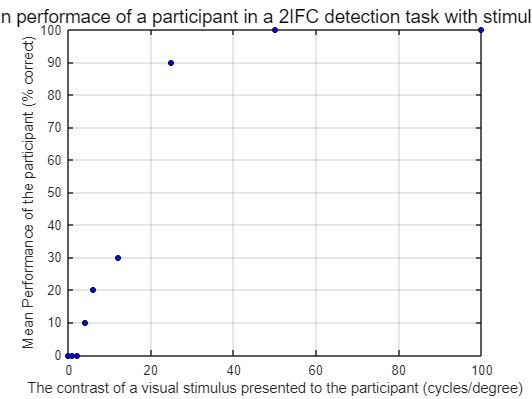

plot(Contrast,MeanPerformance,"ro", "MarkerSize", 4, "MarkerFaceColor", "b", "MarkerEdgeColor", "k")
grid on
title("The mean performace of a participant in a 2IFC detection task with stimulus contrast", "FontSize",14,"FontWeight","normal")
ylabel("Mean Performance of the participant (% correct)", "FontSize",11)
xlabel("The contrast of a visual stimulus presented to the participant (cycles/degree)", "FontSize",11)  

Based on the above data, the contact threshold would be a contrast of 25 (in terms of discrete values) - otherwise a logarithmic trendline would need to be fitted to this data to find thhe contact threshold (75% correct?)